# Linear Control Design II - Group Work Problem Module 5

## Description	

A system with three interconnected tanks is shown in Fig.1. The tanks have the cross sectional areas $A_1$, $A_2$ and $A_3$. The input flows are proportional to the input voltages, that is


$$q_a = k u_1$$



$$q_b = k u_2$$


The flows follow the square root law and since the pressures in the bottoms of the tanks are proportional to the level, one has 


$$q_1 = c_1 \sqrt{x_1-x_2}$$



$$q_2 = c_2 \sqrt{x3-x2}$$



$$q_0 = c_0 \sqrt{x_2}$$


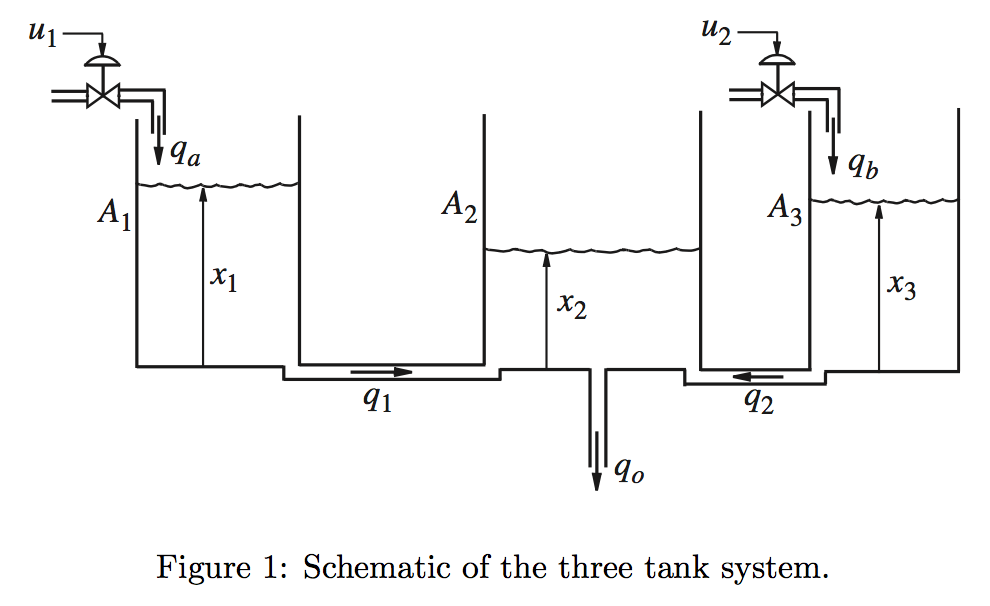				

**Problem 1**  Derive the set of equations describing the system and formulate the nonlinear state model with the two inputs $u_1$ and $u_2$, and the output = $q_0$. 

**Solution:**

Using the mass conversation law, three equations are derived.


$$\dot{x}_1=\frac{1}{A_1}(q_a-q_1)\\
\dot{x}_2=\frac{1}{A_2}(q_1+q_2-q_0)\\
\dot{x}_3=\frac{1}{A_3}(q_b-q_2)$$


The the nonlinear state space model is derived.


$$\mathbf{f(x,u)}=\mathbf{\dot{x}}=\pmatrix{\dot{x}_1 \cr \dot{x}_2\cr \dot{x}_3}
=\pmatrix{
\frac{1}{A_1}\left(-c_1\sqrt{x_1-x_2}+ku_1\right)
\cr
\frac{1}{A_2}\left(c_1\sqrt{x_1-x_2}+c_2\sqrt{x_e-x_2}-c_0\sqrt{x_2}\right)
\cr
\frac{1}{A_3}\left(-c_2\sqrt{x_3-x_2}+ku_2\right)
}$$



$$\mathbf{g(x,u)}=y=q_0=c_0\sqrt{x_2}$$


**Problem 2**  Find the stationary point under the assumption that the inputs are $u_1 = u_{10}$ and $u_2 = u_{20}$. 					

**Solution:**

Setting the time derivatives to zero to obtain stationary states.


$$\dot{x}_1 = 0 \Rightarrow k u_{10} = c_1 \sqrt{x_{10}-x_{20}} \\ \dot{x}_2 = 0 \Rightarrow c_1 \sqrt{x_{10}-x_{20}} + c_2 \sqrt{x_{30}-x_{20}} = c_0 \sqrt{x_{20}} \\ \dot{x}_3 = 0 \Rightarrow k u_{20} = c_2 \sqrt{x_{30}-x_{20}}$$



$$k u_{10} + k u_{20} = c_0 \sqrt{x_{20}} \Rightarrow x_{20} = \left(\frac{k}{c_0} (u_{10}+u_{20})\right)^{2}
$$



$$x_{10} = \left(\frac{k}{c_1} u_{10} \right)^{2} + x_{20} \\ x_{30} = \left(\frac{k}{c_2} u_{20} \right)^{2} + x_{20}$$


The stationary output is 


$$y_0=C_0\sqrt{x_{20}}$$


Solving this symbolically in Matlab can be done as follows:

% Declare the symbols
syms c0 c1 c2 A1 A2 A3 x1 x2 x3 k u1 u2
syms x10 x20 x30 u10 u20 q


Define the nonlinear state-space model

f1 = (-c1*sqrt(x1-x2)+k*u1)/A1;
f2 = (c1*sqrt(x1-x2)+c2*sqrt(x3-x2)-c0*sqrt(x2))/A2;
f3 = (-c2*sqrt(x3-x2)+k*u2)/A3;
f=[f1;f2;f3]

$$f = \left(\begin{array}{c} \frac{k\,u_{1}-c_{1}\,\sqrt{x_{1}-x_{2}}}{A_{1}}\\ \frac{c_{1}\,\sqrt{x_{1}-x_{2}}-c_{0}\,\sqrt{x_{2}}+c_{2}\,\sqrt{x_{3}-x_{2}}}{A_{2}}\\ \frac{k\,u_{2}-c_{2}\,\sqrt{x_{3}-x_{2}}}{A_{3}} \end{array}\right)$$

x = [x1;x2;x3];
u = [u1;u2];
g = c0*sqrt(x2);

Solve the system of three equations with three unknows.

The **stationary points** are given by

solVar = solve([f1==0,f2==0,f3==0],[x1,x2,x3]);

x10=

disp(subs(simplify(solVar.x1),[u1,u2],[u10,u20]))

$$\frac{k^{2}\,\left({c_{0}}^{2}\,{u_{10}}^{2}+{c_{1}}^{2}\,{u_{10}}^{2}+2\,{c_{1}}^{2}\,u_{10}\,u_{20}+{c_{1}}^{2}\,{u_{20}}^{2}\right)}{{c_{0}}^{2}\,{c_{1}}^{2}}$$

x20=

disp(subs(simplify(solVar.x2),[u1,u2],[u10,u20]))

$$\frac{k^{2}\,{\left(u_{10}+u_{20}\right)}^{2}}{{c_{0}}^{2}}$$

x30=

disp(subs(simplify(solVar.x3),[u1,u2],[u10,u20]))

$$\frac{k^{2}\,\left({c_{0}}^{2}\,{u_{20}}^{2}+{c_{2}}^{2}\,{u_{10}}^{2}+2\,{c_{2}}^{2}\,u_{10}\,u_{20}+{c_{2}}^{2}\,{u_{20}}^{2}\right)}{{c_{0}}^{2}\,{c_{2}}^{2}}$$

y0=

disp(subs(g,[x1,x2,x3,u1,u2],[x10,x20,x30,u10,u20]))

$$c_{0}\,\sqrt{x_{20}}$$

**Problem 3**  Linearize the model and derive the linear state space model

            Process equation:  $\Delta \dot{\mathbf{x}} =\mathbf{A} \Delta \mathbf{x} + \mathbf{B} \Delta \mathbf{u}$

            Output equation:    $\Delta \mathbf{y} = \mathbf{C} \Delta \mathbf{x}$

**Solution**

The incremental variables are chosen to be


$$\matrix{x_1 = x_{10} + \Delta x_1 &&&&& u_1 = u_{10} + \Delta u_1 \cr x_2 = x_{20} + \Delta x_2 &&&&& u_2 = u_{20} + \Delta u_2 \cr x_3 = x_{30} + \Delta x_3 &&&&& y = y_{0} + \Delta y}$$


The state space matrices can then be found as


$$\mathbf{A} = \left.\frac{\partial \mathbf{f}}{\partial \mathbf{x}}\right|_\mathbf{0} = \pmatrix{\frac{-c_1}{2A_1\sqrt{x_{10}-x_{20}}} && \frac{c_1}{2A_1\sqrt{x_{10}-x_{20}}} && 0 \cr \frac{c_1}{2A_2\sqrt{x_{10}-x_{20}} } && \frac{-c_1}{2A_2\sqrt{x_{10}-x_{20}}}-\frac{-c_0}{2A_2\sqrt{x_{20}}}-\frac{c_2}{2A_2\sqrt{x_{30}-x_{20}}} && \frac{c_2}{2A_2\sqrt{x_{30}-x_{20}}}  \cr 0 && \frac{c_2}{2A_3\sqrt{x_{30}-x_{20}}} && \frac{-c_2}{2A_3\sqrt{x_{30}-x_{20}}}} \\ \mathbf{B} = \left.\frac{\partial \mathbf{f}}{\partial \mathbf{u}}\right|_\mathbf{0} = \pmatrix{\frac{k}{A_1} & 0 \cr 0 & 0 \cr 0 & \frac{k}{A_3} }, \qquad \mathbf{C} = \left.\frac{\partial \mathbf{g}}{\partial \mathbf{x}}\right|_\mathbf{0} = \pmatrix{0 & \frac{c_0}{2\sqrt{x_{20}}} & 0}, \qquad \mathbf{D} = \left.\frac{\partial \mathbf{g}}{\partial \mathbf{u}}\right|_\mathbf{0} = \pmatrix{0 & 0}$$


This can be performed symbolically in Matlab as follows

% Your solution goes here:
A = subs(jacobian(f,x),[x1 x2 x3 u1 u2],[x10 x20 x30 u10 u20])

$$A = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{2} & \sigma_{2} & 0\\ \frac{c_{1}}{2\,A_{2}\,\sqrt{x_{10}-x_{20}}} & -\frac{\frac{c_{0}}{2\,\sqrt{x_{20}}}+\frac{c_{1}}{2\,\sqrt{x_{10}-x_{20}}}+\frac{c_{2}}{2\,\sqrt{x_{30}-x_{20}}}}{A_{2}} & \frac{c_{2}}{2\,A_{2}\,\sqrt{x_{30}-x_{20}}}\\ 0 & \sigma_{1} & -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{c_{2}}{2\,A_{3}\,\sqrt{x_{30}-x_{20}}}\\ \sigma_{2}=\frac{c_{1}}{2\,A_{1}\,\sqrt{x_{10}-x_{20}}} \end{array}$$

B = subs(jacobian(f,u),[x1 x2 x3 u1 u2],[x10 x20 x30 u10 u20])

$$B = \left(\begin{array}{cc} \frac{k}{A_{1}} & 0\\ 0 & 0\\ 0 & \frac{k}{A_{3}} \end{array}\right)$$

C = subs(jacobian(g,x),[x1 x2 x3 u1 u2],[x10 x20 x30 u10 u20])

$$C = \left(\begin{array}{ccc} 0 & \frac{c_{0}}{2\,\sqrt{x_{20}}} & 0 \end{array}\right)$$

D = subs(jacobian(g,u),[x1 x2 x3 u1 u2],[x10 x20 x30 u10 u20])

$$D = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

Table 1 shows the numerical value of the system’s parameters. The working interval of the input voltages $u_1$ and $u_2$ is 0-10 volts. 

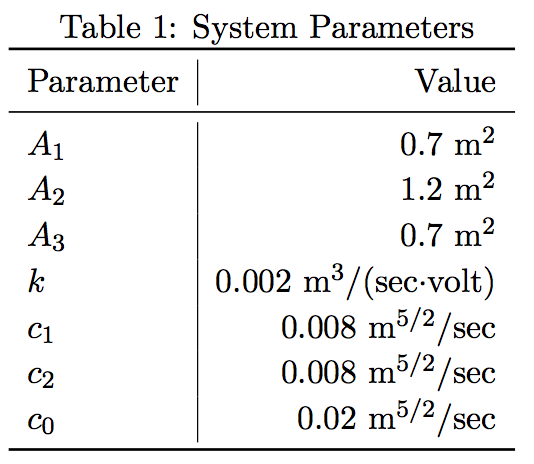

% Define System parameters:
A1 = 0.7;
A2 = 1.2;
A3 = 0.7; 

k = .002; 

c1 = .008; 
c2 = .008;
c0 = .02;

Calculate the stationary point with the given input $u_0=5$v. Based on the manual procedure or Matlab procedure in **problem 2**


$$x_{20} = \left(\frac{k}{c_0} (u_{10}+u_{20})\right)^{2}
$$



$$x_{10} = \left(\frac{k}{c_1} u_{10} \right)^{2} + x_{20} \\ x_{30} = \left(\frac{k}{c_2} u_{20} \right)^{2} + x_{20}$$


The **stationary points** are calculated as:  

u10 = 5;
u20 = 5;
x20 = ((k/c0)*(u10+u20))^2

x20 = 1

x10 = ((k/c1)*u10)^2 + x20

x10 = 2.5625

x30 = ((k/c2)*u20)^2 + x20

x30 = 2.5625

The numerical system matrices

A=

disp(eval(subs(A)))

   -0.0046    0.0046         0
    0.0027   -0.0137    0.0027
         0    0.0046   -0.0046



B=

disp(eval(subs(B)))

    0.0029         0
         0         0
         0    0.0029



C=

disp(eval(subs(C)))

         0    0.0100         0



D=

disp(eval(subs(D)))

     0     0



**Problem 4 ** Set up a Simulink model of the nonlinear system and write a MatLab script to initialize the model with the needed parameter values. Remember that all input variables must be provided with an in port, and all output variables must be provided with an out port in the model. 

x0=zeros(3,1); % initial states

simSwitch = -1; % -1 for step input; 1 for input
u = 5; %input voltage
simopts = simset('FinalStateName','xFinal');% final state as well as the steady state
[t,x,y] = sim('MyModule5_WaterTank',5000,simopts);
xf = xFinal;
disp(['xFinal :' num2str(xf)]);

xFinal :2.5625     0.99999      2.5625


disp(['yFinal:' num2str(y(end))]);

yFinal:0.02


**Problem 5**  Linearize the model using linmod. Set both inputs $u_1 = u_2 = 5$ volts. Simulink by default determine the numbering of the states in the model when linmod is used. It can be a little confusing when comparing Simulinks results with those obtained by manual calculations. If desired, one can determine one’s own numbering in the following way: 

- Choose an integrator in the model and do a right-button click 

- Choose Block Properties. A window opens

- Write the number desired in the Priority-field

- Close the Block Properties window 

simSwitch = 1;
u = 5;

The numerical system matrices(linmod):

% obtain linearized model using linmod applying steady state values for u=5
[Aa,Bb,Cc,Dd] = linmod('MyModule5_WaterTank',xf, [u u]')

Aa =    -0.0046    0.0046         0
    0.0027   -0.0137    0.0027
         0    0.0046   -0.0046


Bb =     0.0029         0
         0         0
         0    0.0029


Cc =          0    0.0100         0


Dd =      0     0


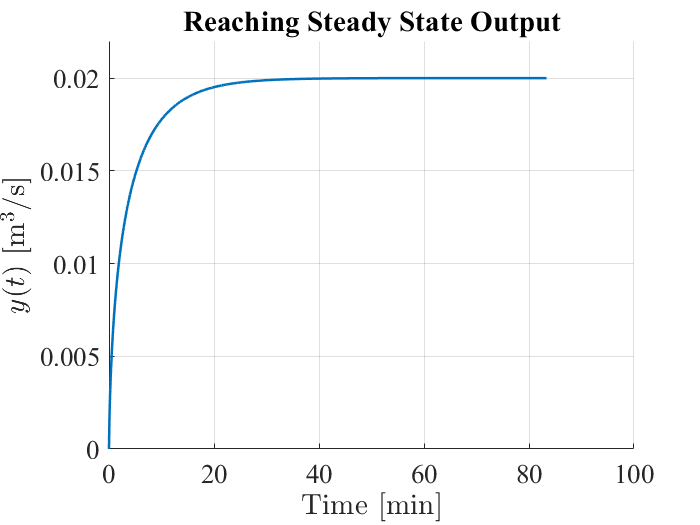

% plot output
figure
h1 = axes;
set(h1,'FontName','times','FontSize', 16)
hold on
grid on
plot(t/60, y, 'LineWidth', 1.5) % time vector is plotted in minutes
title('Reaching Steady State Output')
ylim([0 max(y)*1.1])
xlabel('Time [min]', 'FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$y(t)$ [m$^3$/s]','FontName','times','FontSize',16,'Interpreter','latex')
figure
h2 = axes;
set(h1,'FontName','times','FontSize', 16)

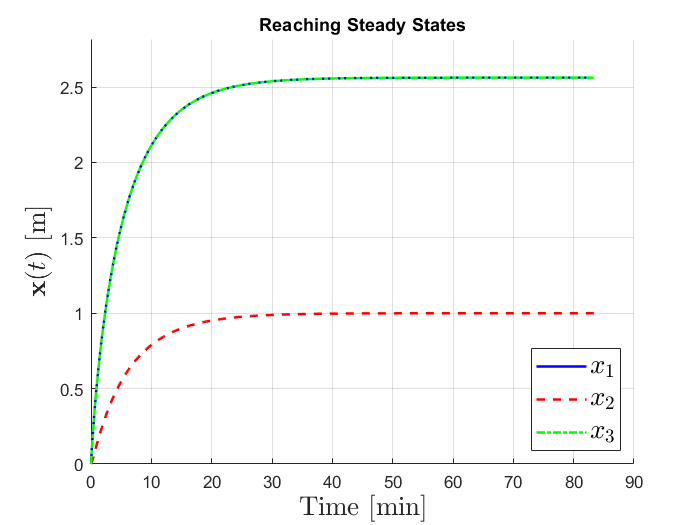

hold on
grid on
plot(t/60, x(:,1), 'b', t/60, x(:,2), '--r',t/60, x(:,3),'-.g', 'LineWidth',1.5)
title('Reaching Steady States')
ylim([0 max(x(:))*1.1])
xlabel('Time [min]', 'FontName','times', 'FontSize',16, 'Interpreter','latex')
ylabel('$\mathbf{x}(t)$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
l = legend('$x_1$', '$x_2$', '$x_3$', 'Location', 'SouthEast');
set(l, 'FontName','times', 'FontSize',16,'Interpreter','latex')

From the graph shows that the state state stays at $x_1 = 2.56\,m, x_2=1\,m, x_3=2.56\,m, y=0.02\,m^3/s$. 5000 seconds are enough for the system to reach steady state.

**Problem 6 ** Simulate the nonlinear and linearized model for small and large variations of the system’s inputs $u_1$ and $u_2$ around their stationary values. Plot the state and output responses and try to determine which is the range of input variations where the linearized model is a good approximation of the nonlinear system. 

**Solution:**

To test if the nonlinear and linearized model are similar around the steady state, the two systmes are simulated by small steps on the input stationary point.

**1)  First to setup the linearized system model using Matlab function: ss()**

**We already have the new setup of linearized system matrixs Aa Bb Cc Dd**

sys = ss(Aa, Bb, Cc, Dd);
sys.u = {'u1','u2'};
sys.y = {'y'};
runl = 20000;
T = 0:0.1:runl;

**2) Input signals set as small deviations from the stationary input value(+/- 0.5v)**

U1 = 0;
Us = U1 * ones(length(T),2);
Us(25000:75000,1) = U1+.5;
Us(50000:100000,2) = U1+.5;
Us(125000:175000,1) = U1-.5;
Us(150000:175000,2) = U1-.5;
inp = zeros(length(T),3);

**3) Linear model simulation**

[yl, tl, xl] = lsim(sys, Us, T);
yl = yl+0.02; % 0.02 is the steady state y value
xl(:,1) = xl(:,1)+xf(1);
xl(:,2) = xl(:,2)+xf(2);
xl(:,3) = xl(:,3)+xf(3);

**4) Nonlinear model simulation**

Us = Us+5;
inp(:,1) = T';
inp(:,2:3)=Us;
x0=xf; % starts at linearization point
[t1, x1, y1]=sim('MyModule5_WaterTank',runl,[],inp);

**5) Potting the resluts**

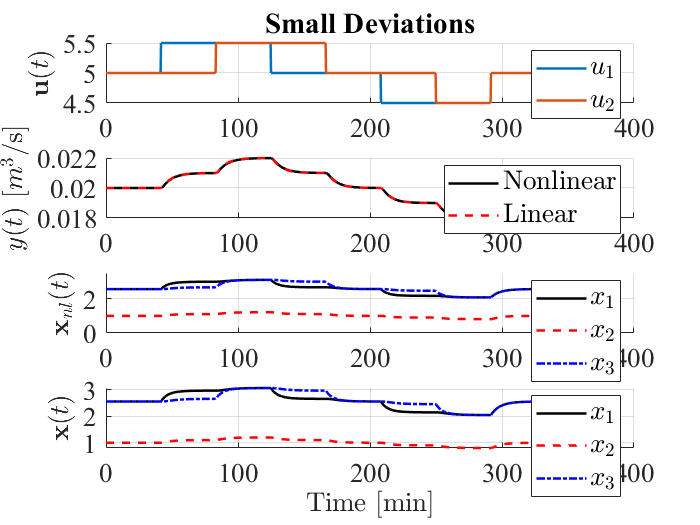

figure

% plot small deiations Us
h3 = subplot(4,1,1);
set(h3, 'FontName','times','Fontsize', 16);
title('Small Deviations');
hold on 
grid on
plot(t1/60, Us, 'LineWidth',1.5);
ylabel('$\mathbf{u}(t)$','FontName','times','FontSize',16,'Interpreter','latex');
l = legend('$u_1$','$u_2$', 'Location',"northeast");
set(l, 'FontName','times','FontSize',16,'Interpreter','latex');

% plot y(t)
h4 = subplot(4,1,2);
set(h4, 'FontName','times','Fontsize', 16);
hold on 
grid on
plot(t1/60, y1, 'k', tl/60, yl, '--r', 'LineWidth',1.5);
ylabel('$y(t)$ [$m^3$/s]','FontName','times', 'FontSize',16,'Interpreter',"latex");
hold off
l = legend('Nonlinear','Linear', 'Location',"northeast");
set(l, 'FontName','times','FontSize',16,'Interpreter','latex');

% plot nonlinear responce
h5 = subplot(4,1,3);
set(h5, 'FontName','times','Fontsize', 16);
hold on 
grid on
plot(t1/60, x1(:,1),'k', t1/60, x1(:,2),'--r',t1/60, x1(:,3),'-.b','LineWidth',1.5);
ylabel('$\mathbf{x}_{nl}(t)$','FontName','times', 'FontSize',16,'Interpreter',"latex");
l = legend('$x_1$','$x_2$', '$x_3$','Location',"northeast");
set(l, 'FontName','times','FontSize',16,'Interpreter','latex');
ylim([0 3.5])

% plot linear system responce
h6 = subplot(4,1,4);
set(h6, 'FontName','times','Fontsize', 16);
hold on 
grid on
plot(tl/60, xl(:,1),'k', tl/60, xl(:,2),'--r', tl/60, xl(:,3), '-.b','LineWidth',1.5);
xlabel('Time [min]', 'FontName','times', 'FontSize',16,'Interpreter',"latex");
ylabel('$\mathbf{x}(t)$','FontName','times', 'FontSize',16,'Interpreter',"latex");
hold off;
l = legend('$x_1$','$x_2$','$x_3$','Location',"northeast");
set(l, 'FontName','times','FontSize',16,'Interpreter','latex');

**2.2) Simulating for large deviation from the stationary input value (+/- 2.5v)**

U1 = 0;
Ul = U1*ones(length(T),2);
Ul(25000:75000,1) = U1+2.5;
Ul(50000:100000,2) = U1+2.5;
Ul(125000:175000,1)=U1-2.5;
Ul(150000:175000,2)=U1-2.5;
inp = zeros(length(T),3); 

**2.3) Linear Model**

[ylb,tlb,xlb] = lsim(sys,Ul,T); 
ylb = ylb+0.02;
xlb(:,1) = xlb(:,1)+xf(1);
xlb(:,2) = xlb(:,2)+xf(2);
xlb(:,3) = xlb(:,3)+xf(3);

**2.4) Nonlinear Model**

Ul = Ul+5;
inp(:,1) = T';
inp(:,2:3) = Ul;
[t1b,x1b,y1b] = sim('MyModule5_WaterTank',runl,[],inp); 

**5) plotting**

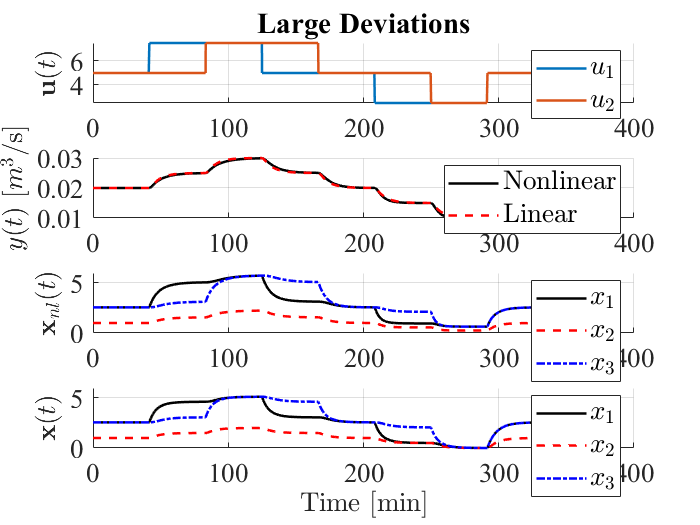

figure

% plot small deiations Us
h7 = subplot(4,1,1);
set(h7, 'FontName','times','Fontsize', 16);
title('Large Deviations');
hold on 
grid on
plot(t1/60, Ul, 'LineWidth',1.5);
ylabel('$\mathbf{u}(t)$','FontName','times','FontSize',16,'Interpreter','latex');
l = legend('$u_1$','$u_2$', 'Location',"northeast");
set(l, 'FontName','times','FontSize',16,'Interpreter','latex');

% plot y(t)
h8 = subplot(4,1,2);
set(h8, 'FontName','times','Fontsize', 16);
hold on 
grid on
plot(t1b/60, y1b, 'k', tlb/60, ylb, '--r', 'LineWidth',1.5);
ylabel('$y(t)$ [$m^3$/s]','FontName','times', 'FontSize',16,'Interpreter',"latex");
hold off
l = legend('Nonlinear','Linear', 'Location',"northeast");
set(l, 'FontName','times','FontSize',16,'Interpreter','latex');

% plot nonlinear responce
h9 = subplot(4,1,3);
set(h9, 'FontName','times','Fontsize', 16);
hold on 
grid on
plot(t1b/60, x1b(:,1),'k', t1b/60, x1b(:,2),'--r',t1b/60, x1b(:,3),'-.b','LineWidth',1.5);
ylabel('$\mathbf{x}_{nl}(t)$','FontName','times', 'FontSize',16,'Interpreter',"latex");
l = legend('$x_1$','$x_2$', '$x_3$','Location',"northeast");
set(l, 'FontName','times','FontSize',16,'Interpreter','latex');
ylim([0 6])

% plot linear system responce
h10 = subplot(4,1,4);
set(h10, 'FontName','times','Fontsize', 16);
hold on 
grid on
plot(tlb/60, xlb(:,1),'k', tlb/60, xlb(:,2),'--r', tlb/60, xlb(:,3), '-.b','LineWidth',1.5);
xlabel('Time [min]', 'FontName','times', 'FontSize',16,'Interpreter',"latex");
ylabel('$\mathbf{x}(t)$','FontName','times', 'FontSize',16,'Interpreter',"latex");
hold off;
l = legend('$x_1$','$x_2$','$x_3$','Location',"northeast");
set(l, 'FontName','times','FontSize',16,'Interpreter','latex');
ylim([0 6])

The Figure **"Large Deviations"** shows that for larger steps the linearised model is no longer valid in describing the dynamics of the original system. 

small differences on the result of states.

**Problem 7**  Determine the transfer functions from u1 to y and from u2 to y. 

**Solution:**

The two identical transfer functions are found using function tf() on the state-space system 

G = tf(sys)

G =
 
  From input "u1" to output "y":
            7.619e-08 s + 3.483e-10
  -------------------------------------------
  s^3 + 0.02281 s^2 + 0.0001215 s + 1.742e-07
 
  From input "u2" to output "y":
            7.619e-08 s + 3.483e-10
  -------------------------------------------
  s^3 + 0.02281 s^2 + 0.0001215 s + 1.742e-07
 
Continuous-time transfer function.



Check the Poles and Zeros of  the transfer functions

From u1 -> y:

p_yu = pole(G(1,1))

p_yu =    -0.0158
   -0.0046
   -0.0024


z_yu = zero(G(1,1))

z_yu = -0.0046

**Problem 8**  Choose a suitable sampling time $T_s$ and discretize the system obtained in Problem 5 using the Matlab$\mathtt{c2d}$-function. Calculate the eigenvalues of the discretized system both using the Matlab $\mathtt{eig}$-function and Frobenius theorem. Compare the obtained results. 

**Solution:**

If sample 5 times in the smallest time contants,

T=round((1/max(abs(p_yu)))/5)

T = 13

% Your solution goes here:
[F,G] = c2d(Aa,Bb,T)

F =     0.9432    0.0529    0.0009
    0.0308    0.8390    0.0308
    0.0009    0.0529    0.9432


G =     0.0361    0.0000
    0.0006    0.0006
    0.0000    0.0361


sysd = ss(F,G,Cc,Dd);
eig(F)

ans =     0.8140
    0.9423
    0.9692
